%% Quaternion Basics Homework
% File: quaternion_basics_homework.m

%% Include namespace (as requested)
try
    include_namespace_dq;
catch
    warning('include_namespace_dq not found. Using built-in functions.');
end

%% Helper functions for quaternions
% Quaternion format: q = [w; x; y; z] where w is scalar, [x;y;z] is vector

function q = axis_angle_to_quat(axis, theta)
    % Convert axis-angle to quaternion
    axis = axis / norm(axis);
    q = [cos(theta/2); sin(theta/2) * axis];
end

function q = quat_multiply(q1, q2)
    % Hamilton product: q1 * q2
    w1 = q1(1); v1 = q1(2:4);
    w2 = q2(1); v2 = q2(2:4);
    w = w1*w2 - dot(v1, v2);
    v = w1*v2 + w2*v1 + cross(v1, v2);
    q = [w; v];
end

function qc = quat_conjugate(q)
    % Conjugate of quaternion
    qc = [q(1); -q(2:4)];
end

function qi = quat_inverse(q)
    % Inverse of quaternion
    norm_sq = sum(q.^2);
    qi = quat_conjugate(q) / norm_sq;
end

function v_rot = rotate_vector(q, v)
    % Rotate vector v by quaternion q
    qv = [0; v(:)];
    result = quat_multiply(quat_multiply(q, qv), quat_conjugate(q));
    v_rot = result(2:4);
end

%% 2) Store r1 - rotation of pi/8 rad about x-axis
r1 = axis_angle_to_quat([1; 0; 0], pi/8);
fprintf('2) r1 = [%.6f; %.6f; %.6f; %.6f]\n', r1);

2) r1 = [0.980785; 0.195090; 0.000000; 0.000000]



%% 3) Store r2 - rotation of pi/16 rad about y-axis
r2 = axis_angle_to_quat([0; 1; 0], pi/16);
fprintf('3) r2 = [%.6f; %.6f; %.6f; %.6f]\n', r2);

3) r2 = [0.995185; 0.000000; 0.098017; 0.000000]



%% 4) Store r3 - rotation of pi/32 rad about z-axis
r3 = axis_angle_to_quat([0; 0; 1], pi/32);
fprintf('4) r3 = [%.6f; %.6f; %.6f; %.6f]\n', r3);

4) r3 = [0.998795; 0.000000; 0.000000; 0.049068]



%% 5) Sequential rotation: apply r1, then r2, then r3, store in r4
r4 = quat_multiply(r3, quat_multiply(r2, r1));
fprintf('\n5) r4 (sequential rotation) = [%.6f; %.6f; %.6f; %.6f]\n', r4);


5) r4 (sequential rotation) = [0.975825; 0.189200; 0.105545; 0.028794]


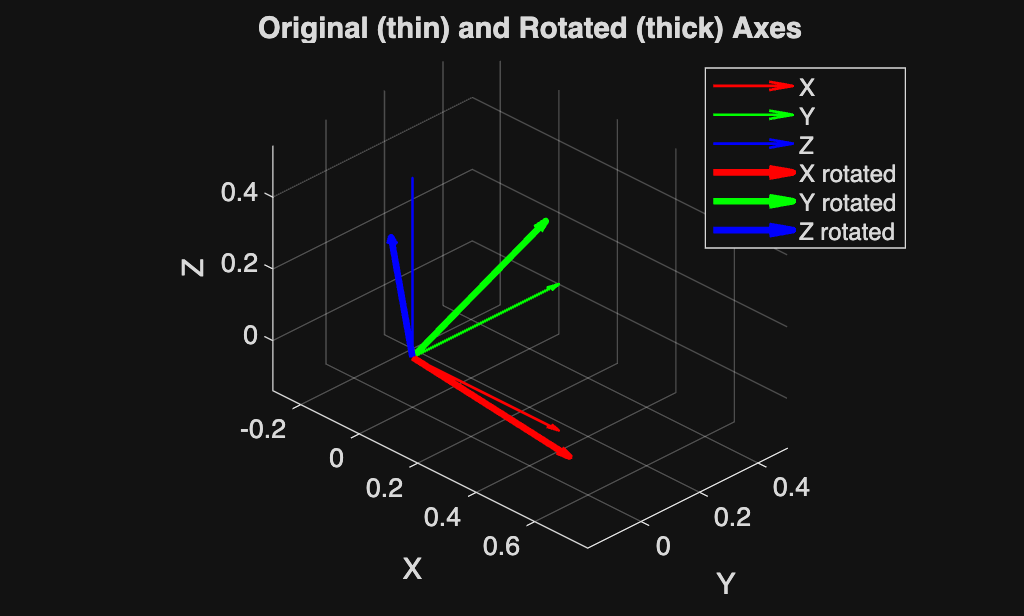


% Plot r4
figure('Name', 'Rotated Frame r4');
hold on; axis equal; grid on;

% Original basis vectors
ex = [1;0;0]; ey = [0;1;0]; ez = [0;0;1];
quiver3(0,0,0, ex(1),ex(2),ex(3), 0.5, 'r', 'LineWidth', 1);
quiver3(0,0,0, ey(1),ey(2),ey(3), 0.5, 'g', 'LineWidth', 1);
quiver3(0,0,0, ez(1),ez(2),ez(3), 0.5, 'b', 'LineWidth', 1);

% Rotated basis vectors
ex_rot = rotate_vector(r4, ex);
ey_rot = rotate_vector(r4, ey);
ez_rot = rotate_vector(r4, ez);
quiver3(0,0,0, ex_rot(1),ex_rot(2),ex_rot(3), 0.5, 'r', 'LineWidth', 2.5);
quiver3(0,0,0, ey_rot(1),ey_rot(2),ey_rot(3), 0.5, 'g', 'LineWidth', 2.5);
quiver3(0,0,0, ez_rot(1),ez_rot(2),ez_rot(3), 0.5, 'b', 'LineWidth', 2.5);

title('Original (thin) and Rotated (thick) Axes');
xlabel('X'); ylabel('Y'); zlabel('Z');
legend('X', 'Y', 'Z', 'X rotated', 'Y rotated', 'Z rotated');
view(45, 30);
hold off;


%% 6) Find reverse rotation r5 (inverse of r4)
r5 = quat_inverse(r4);
fprintf('\n6) r5 (inverse of r4) = [%.6f; %.6f; %.6f; %.6f]\n', r5);


6) r5 (inverse of r4) = [0.975825; -0.189200; -0.105545; -0.028794]



%% 7) Rotate r4 by 360° about x-axis and store in r6
full_rotation_x = axis_angle_to_quat([1;0;0], 2*pi);
r6 = quat_multiply(full_rotation_x, r4);
fprintf('\n7) r6 (r4 rotated 360° about x) = [%.6f; %.6f; %.6f; %.6f]\n', r6);


7) r6 (r4 rotated 360° about x) = [-0.975825; -0.189200; -0.105545; -0.028794]



% Check if r6 equals -r4
diff_r4 = norm(r6 - r4);
diff_neg_r4 = norm(r6 + r4);
fprintf('   ||r6 - r4|| = %.6e\n', diff_r4);

   ||r6 - r4|| = 2.000000e+00


fprintf('   ||r6 - (-r4)|| = %.6e\n', diff_neg_r4);

   ||r6 - (-r4)|| = 1.118863e-16



if diff_neg_r4 < 1e-10
    fprintf('   r6 = -r4 (same rotation, quaternion double cover)\n');
elseif diff_r4 < 1e-10
    fprintf('   r6 = r4\n');
end

   r6 = -r4 (same rotation, quaternion double cover)


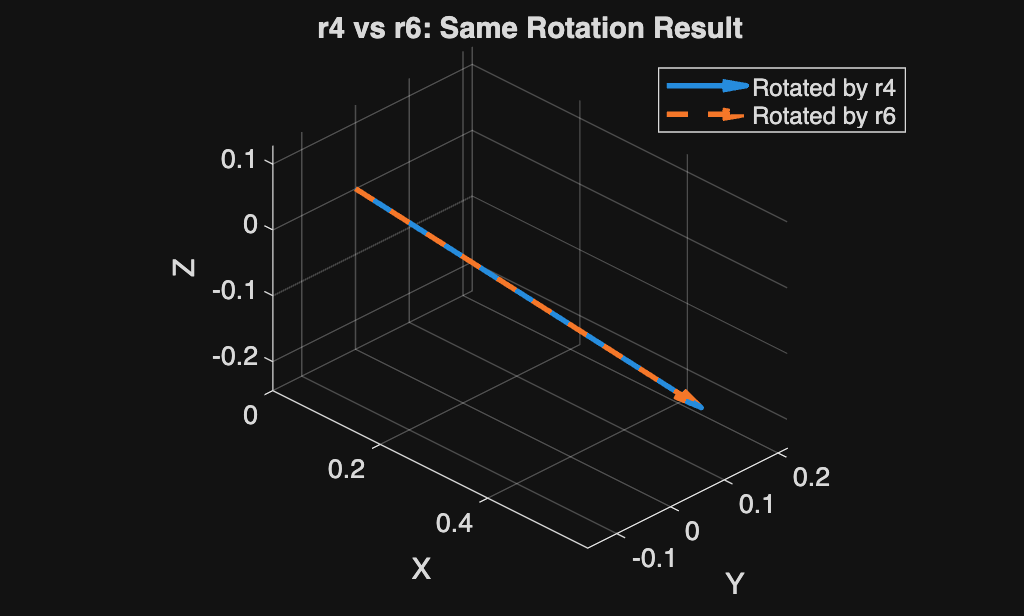


% Plot comparison
test_vec = [1; 0; 0];
vec_r4 = rotate_vector(r4, test_vec);
vec_r6 = rotate_vector(r6, test_vec);

figure('Name', 'Compare r4 and r6');
hold on; axis equal; grid on;
quiver3(0,0,0, vec_r4(1), vec_r4(2), vec_r4(3), 0.6, 'LineWidth', 2);
quiver3(0,0,0, vec_r6(1), vec_r6(2), vec_r6(3), 0.6, 'LineWidth', 2, 'LineStyle', '--');
legend('Rotated by r4', 'Rotated by r6');
title('r4 vs r6: Same Rotation Result');
xlabel('X'); ylabel('Y'); zlabel('Z');
view(45, 30);
hold off;


%% Bonus Homework
fprintf('\n--- Bonus Homework ---\n');


--- Bonus Homework ---



% 1) Quaternion multiplication example
h1 = [0.9; 0.3; 0.2; 0.1];
h2 = [0.8; 0.1; 0.4; 0.3];
h3 = quat_multiply(h1, h2);
fprintf('Bonus 1) h1*h2 = [%.6f; %.6f; %.6f; %.6f]\n', h3);

Bonus 1) h1*h2 = [0.580000; 0.350000; 0.440000; 0.450000]



% 2) Quaternion norm
norm_h1 = sqrt(sum(h1.^2));
fprintf('Bonus 2) ||h1|| = %.6f\n', norm_h1);

Bonus 2) ||h1|| = 0.974679



% 3) Unit quaternion has unit norm
phi = pi/7;
u = [0.5; 0.3; -0.2]; 
u = u / norm(u);
unit_q = [cos(phi); sin(phi)*u];
norm_unit = sqrt(sum(unit_q.^2));
fprintf('Bonus 3) Unit quaternion norm = %.12f (should be 1.0)\n', norm_unit);

Bonus 3) Unit quaternion norm = 1.000000000000 (should be 1.0)



fprintf('\nHomework complete!\n');


Homework complete!
